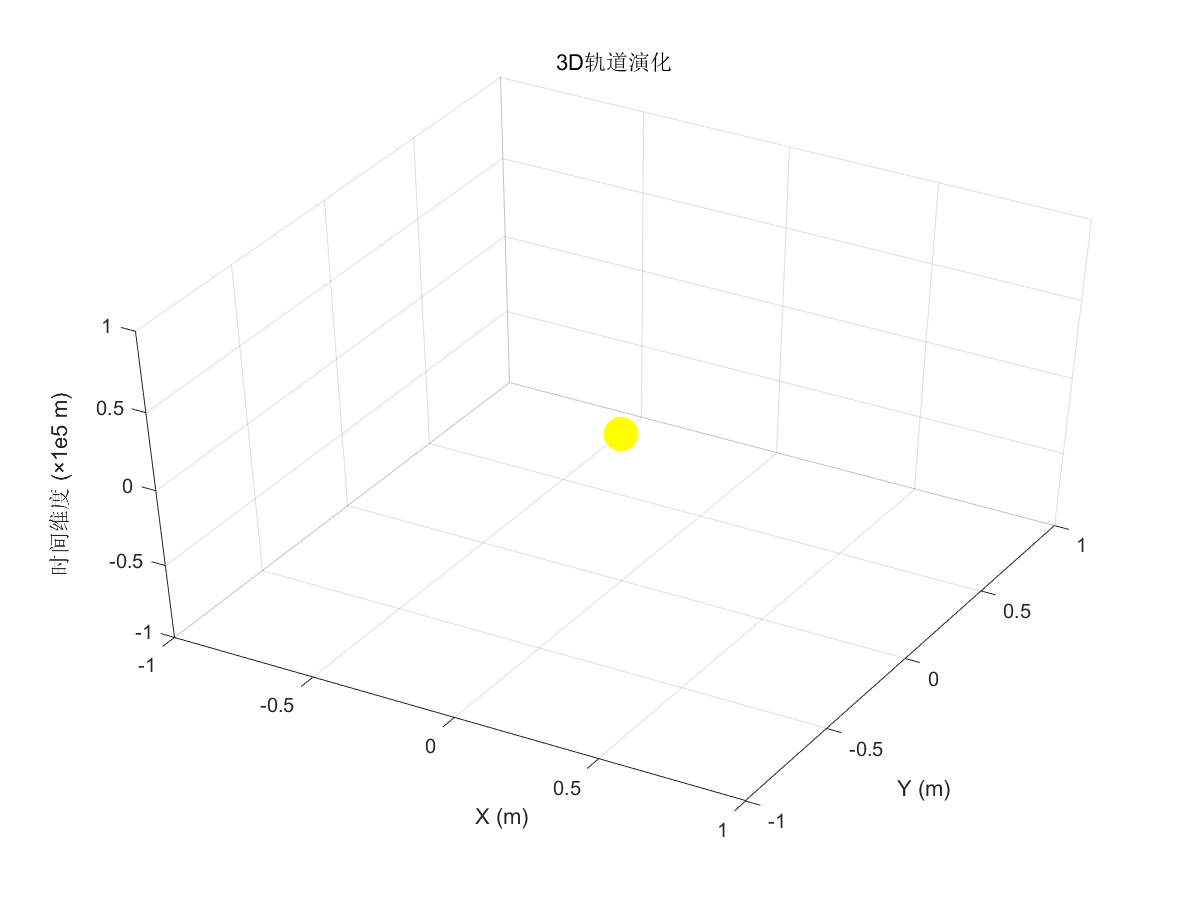

sim_params = struct(...
    'N', 300, ...            % 初始小行星数量
    'R_orbit', 1.5e11, ...   % 标称轨道半径(m)
    'dt', 86400, ...         % 时间步长(s) = 1天
    'max_steps', 365*3, ...  % 最大模拟时长(3年)
    'collision_radius', 2e6, ... % 碰撞判定半径(m)
    'physics_mode', 1, ...   % 1=简化模型 2=完整模型
    'visual_freq', 10, ...   % 可视化更新频率(时间步)
    'distribution', 'uniform', ... % ★★★ 新增分布类型参数 ★★★
    'sigma', 0.1 ...         % ★★★ 高斯分布标准差系数 ★★★
);
sim_params.N = 100;          % 初始数量
sim_params.max_steps = 50;   % 最大步数
sim_params.visual_freq = 5;  % 每5步更新可视化

% ================= 初始化系统 =================
[asteroids, init_params] = initialize_asteroids1(sim_params);
history = struct('pos', cell(1, sim_params.max_steps), 't', []); % 历史记录

% ================= 主循环 =================
log = struct('t', [], 'N', [], 'merges', 0);
figure; % 预创建可视化窗口

for step = 1:sim_params.max_steps
    % 碰撞检测与处理
    [pairs] = collision_detection(asteroids, sim_params.collision_radius);
    if ~isempty(pairs)
        [asteroids, merges] = process_collisions(asteroids, pairs);
        log.merges = log.merges + merges;
    end
    
    % 轨道运动更新
    if sim_params.physics_mode == 1
        asteroids = orbital_motion_simple(asteroids, sim_params.dt);
    else
        asteroids = orbital_motion_full(asteroids, sim_params.dt);
    end
    
    % 记录数据
    log.t(end+1) = step * sim_params.dt;
    log.N(end+1) = length(asteroids);
    history(step).pos = reshape([asteroids.pos], 2, [])'; % 记录位置
    
    % 实时可视化
    if mod(step, sim_params.visual_freq) == 0
        show_dynamics(asteroids, step, log);
    end
    
    % 终止条件
    if length(asteroids) <= 1
        break;
    end
end

% ================= 后期可视化 =================
% 生成三维轨道图
plot_3d_orbits(history(1:sim_params.visual_freq:end));

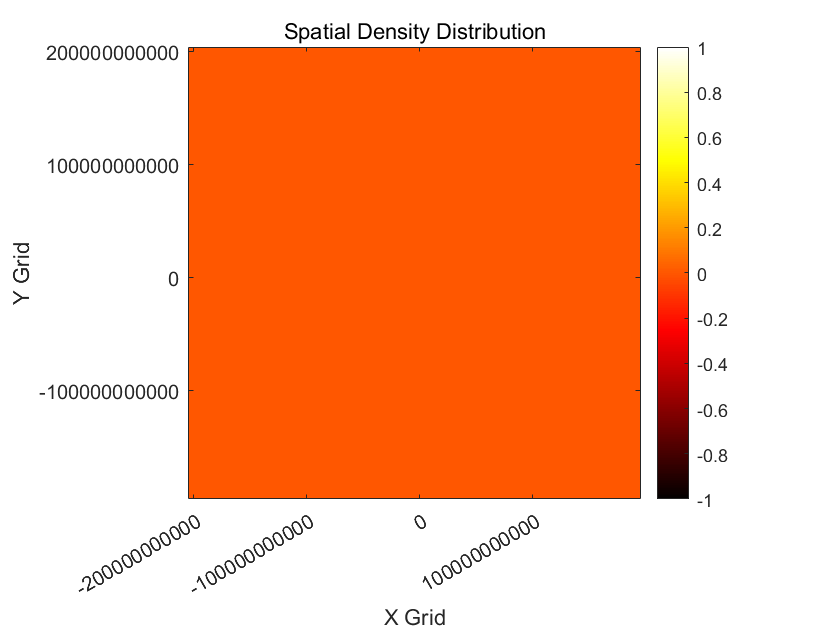


% 显示最终密度分布
plot_density_heatmap(asteroids);


% ================= 结果分析 =================
fprintf('模拟结果统计:\n');

模拟结果统计:


fprintf('初始天体数: %d\n', sim_params.N);

初始天体数: 100


fprintf('最终天体数: %d\n', log.N(end));

最终天体数: 0


fprintf('总合并次数: %d\n', log.merges);

总合并次数: 100


fprintf('最大天体质量: %.2e kg\n', max([asteroids.mass]));

最大天体质量:  kg
